# 4-bar linkage analysis** - **`kinematic analysis singularities - PART 2`

Let's explore some of the kinematic singularities of the 4bar linkage shown in Figure_01 below. 

**Figure 01:  the 4bar linkage**

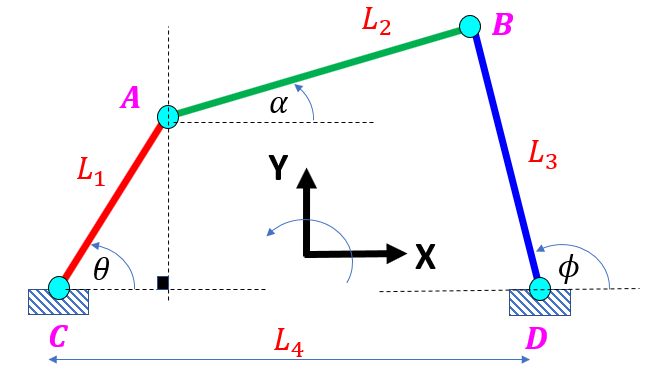

 An alternate kinematics analysis is performed in the file <`DEMO_01b_bh_4bar_analysis_kinematics.mlx`> and it seems to be more "robust" than the approach which we will comment on here

## Define the symbolic geometry parameters:

Recall the kinematic derivation that we saw previously:

syms L_1   L_2  L_3  L_4  theta phi

Let's define the relationships describing horizontal distances:

- 
$$L_4 \;\;=\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)\;+\;\;L_3 \ldotp \mathrm{cos}\left(\pi -\phi \right)$$


- 
$$L_4 \;\;=\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)-\;\;L_3 \ldotp \mathrm{cos}\left(\phi \right)$$


So we see that:

- $\;L_2 \ldotp \mathrm{cos}\left(\alpha \right)\;\;=L_4 \;-\;\;L_1 \ldotp \mathrm{cos}\left(\theta \right)\;+\;\;\;L_3 \ldotp \mathrm{cos}\left(\phi \right)$  ` .....    EQ_1`

And similarly the vertical distance:

- 
$$L_1 \ldotp \mathrm{sin}\left(\theta \right)\;\;+\;\;L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\pi -\phi \right)$$


- 
$$L_1 \ldotp \mathrm{sin}\left(\theta \right)\;\;+\;\;L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\phi \right)$$


So we see that:

- $L_2 \ldotp \mathrm{sin}\left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \mathrm{sin}\left(\phi \right)\;\;-\;\;L_1 \ldotp \mathrm{sin}\left(\theta \right)\;$`.....    EQ_2`

So let's square `EQ_1` and `EQ_2` and add them together

EQ_C = L_2^2 == (L_4 - L_1*cos(theta) + L_3*cos(phi))^2  +  (L_3*sin(phi) - L_1*sin(theta))^2

$$EQ\_C = {L_{2}}^{2}={\left(L_{4}+L_{3}\,\cos\left(\varphi \right)-L_{1}\,\cos\left(\theta \right)\right)}^{2}+{\left(L_{3}\,\sin\left(\varphi \right)-L_{1}\,\sin\left(\theta \right)\right)}^{2}$$

Save a copy of this before we do any symbol sustitutions:

EQ_C_at_the_beginning = EQ_C;

## Looking for $\phi =f\left(\theta \right)$

`EQ_C` is pretty ugly .... but we can use it to find a functional relationship between $\phi$and $\theta$, ie:  $\phi =f\left(\theta \right)$.  A trick that engineers have found (eg: REF_02, 03), is the following. Let:

- 
$$z=\mathrm{tan}\left(\frac{\phi }{2}\right)\;\Longrightarrow \;\;\;\;\mathrm{sin}\left(\phi \right)=\frac{2z}{1+z^2 }\;\;\;\;\;\;\mathrm{and}\;\;\;\;\;\;\;\mathrm{cos}\left(\phi \right)=\frac{1-z^2 }{1+z^2 }\;\;\;\;\;\;$$


This transformation allows us to convert **EQ_C** into a quadratic.  So let's substitute this into `EQ_C` and see what pops out:

syms z
sp   = (2*z)/(1 + z^2);
cp   = (1 - z^2)/(1 + z^2);
EQ_C = subs(EQ_C, {sin(phi), cos(phi)}, {sp, cp})

$$EQ\_C = {L_{2}}^{2}={\left(L_{1}\,\sin\left(\theta \right)-\frac{2\,L_{3}\,z}{z^{2}+1}\right)}^{2}+{\left(L_{1}\,\cos\left(\theta \right)-L_{4}+\frac{L_{3}\,\left(z^{2}-1\right)}{z^{2}+1}\right)}^{2}$$

Note that if we make the assumption that ($\left.z^2 +1\not= 0\right)$, then `EQ_C` is just a quadratic in terms of $z$

simplify( expand(EQ_C) )  % you see that it becomes a quadratic with a condition

$$ans = \begin{array}{l} \sigma_{1}\,\left({L_{1}}^{2}\,z^{2}+{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}\,z^{2}+{L_{3}}^{2}\,z^{2}+{L_{3}}^{2}+2\,L_{3}\,L_{4}+{L_{4}}^{2}\,z^{2}+{L_{4}}^{2}\right)=\sigma_{1}\,\left({L_{2}}^{2}+{L_{2}}^{2}\,z^{2}+2\,L_{1}\,L_{3}\,\cos\left(\theta \right)+2\,L_{1}\,L_{4}\,\cos\left(\theta \right)+2\,L_{3}\,L_{4}\,z^{2}+4\,L_{1}\,L_{3}\,z\,\sin\left(\theta \right)+2\,L_{1}\,L_{4}\,z^{2}\,\cos\left(\theta \right)\right)\wedge z\neq -\mathrm{i}\wedge z\neq \mathrm{i}\\ \mathrm{where}\\ \sigma_{1}={\left(z^{2}+1\right)}^{2} \end{array}$$

`EQ_C` is just a quadratic in terms of $z$, which we can solve for:

the_z = solve(EQ_C, z);
the_z = simplify(the_z)

$$the\_z = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{1}+2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}}\\ -\frac{\sigma_{1}-2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(-{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{4}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)}\\ \sigma_{2}={L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2} \end{array}$$

Keep a copy of the original symbolic expressions:

the_ORIGINAL_z = the_z;

## Pick `MACHINE_E` and explore potential singularities for z1 and z2

[val_L1, val_L2, val_L3, val_L4] = bh_get_preconfigured_machine("MACHINE_E");
[val_L1, val_L2, val_L3, val_L4]

ans =     0.5000    0.5000    0.5000    1.0000


Explore the z roots with numeric values for $L_1 \;,L_2 \;,L_3$ and $L_4$

the_z            = subs(the_ORIGINAL_z, [L_1, L_2, L_3, L_4], [val_L1, val_L2, val_L3, val_L4]);

Specifically, let's explore the 1st root

the_z(1)

$$ans = -\frac{\frac{\sin\left(\theta \right)}{2}+\sqrt{-\left(\cos\left(\theta \right)-\frac{1}{4}\right)\,\left(\cos\left(\theta \right)-\frac{5}{4}\right)}}{\frac{\cos\left(\theta \right)}{2}-\frac{1}{4}}$$

  While you stare at the above equation, NOTE the following:

- 
$$\mathrm{cos}\left(\frac{-\pi }{3}\right)=\;\mathrm{cos}\left(\frac{\pi }{3}\right)=\frac{1}{2}$$


[the_N1, the_D1] = numden(  the_z(1)  );
[the_N2, the_D2] = numden(  the_z(2)  );

Now plot:

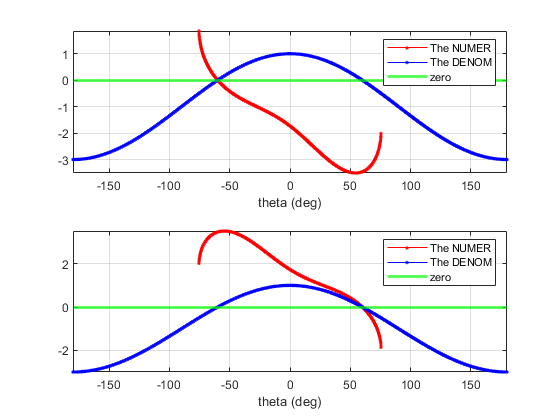

figure;
hax(1) = subplot(2,1,1);   LOC_do_plot_numden(the_N1, the_D1, hax(1));
hax(2) = subplot(2,1,2);   LOC_do_plot_numden(the_N2, the_D2, hax(2));              

For `MACHINE_E` you'll see that we have the situation where there are some values for $\theta$ where the denominator is  ZERO.  For example when $\theta =\;\frac{-\pi }{3}$, eg:

[ subs(the_N1, theta, -pi/3) ,  subs(the_D1, theta, -pi/3)  ]      

$$ans = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

Similarly, when $\theta =\;\frac{+\pi }{3}$, we get the denominator equalling zero, ie:

[ subs(the_N1, theta, pi/3) ,  subs(the_D1, theta, pi/3)  ]      

$$ans = \left(\begin{array}{cc} -2\,\sqrt{3} & 0 \end{array}\right)$$

Has the maths failed ? Have we overlooked a condition ?  The answer lies in in our assumption on the shape of equation C.  Recall that `EQ_C` had the general shape:

- `EQ_C` $={a\ldotp z}^{2\;} \;+\;b\ldotp z\;\;+\;c$

and the symbolic solver discovered this pattern and went ahead and applied a typical root equation, eg:

- 
$$z_{\mathrm{ROOTS}} \;=\frac{-b\;\;\pm \;\sqrt{b^2 \;\;-4\ldotp a\ldotp c}}{2\ldotp a}$$
 

So ? - So what happens if $a=0$ ? 

If  $a=0$ then the use of the typical quadratic root equation is invalid.  So let's revisit `EQ_C` :

my_EQC = EQ_C;
my_EQC = subs(my_EQC, [L_1, L_2, L_3, L_4], [val_L1, val_L2, val_L3, val_L4]);

First consider the case where:

-  
$$\theta =\;\frac{-\pi }{4}$$


 simplify(  subs(my_EQC, theta, -pi/4)  )

$$ans = \frac{2\,\sqrt{2}\,z-3\,\sqrt{2}-\sqrt{2}\,z^{2}+2\,z^{2}+10}{z^{2}+1}=1$$

And note how (via simple rearrangement of terms) we end up with a quadratic. So evaluating our quadratic root formula would be just fine.  

But now consider the case where:

-  
$$\theta =\;\frac{-\pi }{3}$$


simplify(  subs(my_EQC, theta,  -pi/3  ))

$$ans = z=-\sqrt{3}$$

So when $\theta =\;\frac{-\pi }{3}$, ***we do NOT end up with a quadratic equation*** in terms of $z$.  Instead we have a LINEAR equation .... so our application of the quadratic root formula is completely invalid !! - now we know !   

## A strategy for solving at these singularity instances:

So for these "mathematical singularities" you can see and solve them by starting right back at the beginning. Recall `EQ_C`:

EQ_C_at_the_beginning

$$EQ\_C\_at\_the\_beginning = {L_{2}}^{2}={\left(L_{4}+L_{3}\,\cos\left(\varphi \right)-L_{1}\,\cos\left(\theta \right)\right)}^{2}+{\left(L_{3}\,\sin\left(\varphi \right)-L_{1}\,\sin\left(\theta \right)\right)}^{2}$$

Let's substitue numeric values for the link lengths and our problematic angle, immediatly into `EQ_C` :

my_new_EQ_C = subs(EQ_C_at_the_beginning,[L_1, L_2, L_3, L_4], [val_L1, val_L2, val_L3, val_L4] );
my_new_EQ_C = subs(my_new_EQ_C, theta, -pi/3);
simplify(my_new_EQ_C)

$$ans = \sin\left(\varphi +\frac{\pi }{3}\right)=-\frac{\sqrt{3}}{2}$$

So what does this look like ?

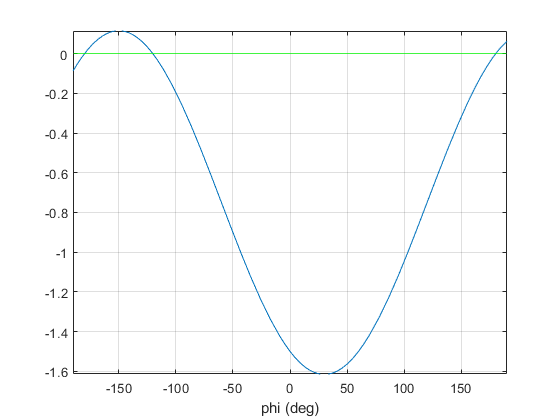

my_func = lhs(my_new_EQ_C) - rhs(my_new_EQ_C);
syms phi_deg_sym real
my_func = subs(my_func, phi, (phi_deg_sym*pi/180));

figure;
    fplot(my_func, [-190, 190]); grid on; xlabel('phi (deg)');
    hold on
    yline(0,'-g');

## Let's do an angle sweep and look at some results:

First recall our EQ_C

my_EQC = EQ_C;
my_EQC = subs(my_EQC, [L_1, L_2, L_3, L_4], [val_L1, val_L2, val_L3, val_L4])

$$my\_EQC = \frac{1}{4}={\left(\frac{\cos\left(\theta \right)}{2}+\frac{z^{2}-1}{2\,\left(z^{2}+1\right)}-1\right)}^{2}+{\left(\frac{\sin\left(\theta \right)}{2}-\frac{z}{z^{2}+1}\right)}^{2}$$

Now let's solve for the z roots of this equation

theta_deg_col   = [-180:5:180]';
theta_rad_col   = deg2rad(theta_deg_col);
N               = length(theta_deg_col);
the_z_mat       = zeros(N,2);
the_N_mat       = zeros(N,2);
the_D_mat       = zeros(N,2);
the_phid_mat    = zeros(N,2);
the_alphad_mat  = zeros(N,2);

for kk=1:length(theta_rad_col)
   the_EQ         = subs(my_EQC, theta, theta_rad_col(kk) );
   the_z          = solve(the_EQ, z); 
   [the_N, the_D] = numden(the_z);
     
   doub_the_z     = double(the_z);
   doub_the_N     = double(the_N);
   doub_the_D     = double(the_D); 
   
   if(2 == length(doub_the_z))
       the_z_mat(kk,:) = [doub_the_z(1), doub_the_z(2)];
       the_N_mat(kk,:) = [doub_the_N(1), doub_the_N(2)];
       the_D_mat(kk,:) = [doub_the_D(1), doub_the_D(2)];      
       
   else
       the_z_mat(kk,:) = [doub_the_z(1), NaN];
       the_N_mat(kk,:) = [doub_the_N(1), NaN];
       the_D_mat(kk,:) = [doub_the_D(1), NaN];  
   end
end

And Let's look at the results

tmp_mat = [theta_deg_col, real(the_z_mat(:,1)),  imag(the_z_mat(:,1)), real(the_z_mat(:,2)),  imag(the_z_mat(:,2)), ...
           the_N_mat(:,1), the_D_mat(:,1), the_N_mat(:,2), the_D_mat(:,2)];
array2table(tmp_mat,"VariableNames", {'theta_deg', 'real_z1','imag_z1','real_z2','imag_z2','N1','D1','N2','D2'})

ans = 73×9 table
    theta_deg     real_z1     imag_z1     real_z2     imag_z2           N1              D1               N2              D2    
    _________    _________    _______    _________    _______    ________________    _________    ________________    _________

      -180               0    -2.2361            0     2.2361     -2.2361+0i              0-1i      2.2361+0i              0-1i
      -175       -0.058252     2.2364    -0.058252    -2.2364    -0.17431+6.6923i    2.9924+0i    -0.17431-6.6923i    2.9924+0i
      -170        -0.11695     2.2376     -0.11695    -2.2376     -0.3473+6.6448i    2.9696+0i     -0.3473-6.6448i    2.9696+0i
      -165        -0.17656     2.239

# Local functions only beyond this point:

function LOC_do_plot_numden(the_N, the_D, hax)
    syms theta

    mlf_the_N     = matlabFunction(the_N, 'Vars', theta);
    mlf_the_D     = matlabFunction(the_D, 'Vars', theta);

    theta_deg_vec = -180:0.1:180;
    theta_rad_vec = deg2rad(theta_deg_vec);
    N             = length(theta_rad_vec);
    
    THE_N_list    = zeros(size(theta_rad_vec));
    THE_D_list    = zeros(size(theta_rad_vec));
        
    for kk=1:N
    
      my_N = mlf_the_N(theta_rad_vec(kk));
      my_D = mlf_the_D(theta_rad_vec(kk));  
        
      if(~isreal(my_N))
          THE_N_list(kk) = NaN;
      else
          THE_N_list(kk) = my_N;
      end
      
      if(~isreal(my_D))
          THE_D_list(kk) = NaN;
      else
          THE_D_list(kk) = my_D;
      end      
    end
    
    plot(hax, theta_deg_vec,  THE_N_list, '-r.');
    hold(hax, 'on');
    plot(hax, theta_deg_vec,  THE_D_list, '-b.');  
    grid(hax,'on');
    xlabel(hax,'theta (deg)'); 
    yline(hax, 0,'-g', 'LineWidth',2);
    axis(hax,'tight')
    legend(hax, ["The NUMER","The DENOM", "zero"]);
    
end

And plotting the Z's:

function LOC_plot_z(the_Z1, the_Z2)

syms theta A

z1 = subs(the_Z1, theta, pi*A/180);
z2 = subs(the_Z2, theta, pi*A/180);

figure;
subplot(2,1,1);  fplot(z1, [-180, 180]);
    xlabel('theta (degs)')
    grid on
    title('z1')
subplot(2,1,2);  fplot(z2, [-180, 180]);
    xlabel('theta (degs)')
    grid on
    title('z2')
    
end